# Application: Solving a Linear Ordinary Differential Equation Using Laplace Transform

## Introduction

Symbolic workflows keep calculations in their natural symbolic form rather than numerical form. This approach helps to understand the solution's properties and uses exact symbolic values. Numbers are substituted for symbolic variables only when a numerical result is required or cannot be continued in a symbolic manner.  

Typically, the steps are:

- Declare the variables and the equations.

- Solve the equations using the Laplace transform.

- Substitute numerical values.

- Plot the results.

- Analyse the results.

## Solution of a Second-Order Linear Differential Equation

We want to solve the ODE equation:


$$\frac{d^2\, y(t)}{d\,t^2} + 3 \frac{d\, y(t)}{d\,t} +2 y(t) = \left[1+3t\right]\cdot 1(t)$$


with initial conditions


$$y(0) = 1 \quad ,\qquad \left.\frac{d\,y}{dt} \right\vert_{t=0} =0$$


### Step 0: Declare the Variables

clear

syms t y(t) u(t) Y s % the variables in the time and frequency domain
assume(t >=0)

u = (1+3*t); % Note: you DO NOT NEED to explicity write the Heaviside function!

y0VAL = 1;
doty0VAL = 0; % the initial conditions

### Step 1: Declare the ODE 

Firstly, declare the symbolic derivatives $\dot y$ and $\ddot y$ of the function $y(t)$

dot_y = diff(y,t);
ddot_y = diff(dot_y,t);

Then, declare the ODE equation. **Pay atttention to the == symbol**

eqnODE = ddot_y + 3*dot_y + 2*y == u;

What does the equation look like?

disp(eqnODE)

$$\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=3\,t+1$$

### Step 2 & 3: Solve the ODE Using the Laplace Transform & Substitute Numerical Values

Let's compute the Laplace transform of the ODE:

eqnLT = laplace(eqnODE, t, s);

What does the equation in the Laplace transform domain look like?

disp(eqnLT)

$$3\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-3\,y\left(0\right)-s\,y\left(0\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}$$

**Note**: In order to continue and solve the algebraic equation with the Laplace transform, we must replace all terms indicating Laplace transforms of the function $y(t)$ and its derivatives with the symbolic variables.

eqnLT1 = subs(eqnLT,laplace(y,t,s),Y)

$$eqnLT1 = 2\,Y-3\,y\left(0\right)+3\,Y\,s-s\,y\left(0\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+Y\,s^{2}=\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}$$

eqnLT2 = subs(eqnLT1, y(0), y0VAL)

$$eqnLT2 = 2\,Y-s+3\,Y\,s-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+Y\,s^{2}-3=\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}$$

eqnLT3 = subs(eqnLT2, subs(diff(y(t), t), t, 0), doty0VAL)

$$eqnLT3 = 2\,Y-s+3\,Y\,s+Y\,s^{2}-3=\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}$$

Finally, **solve the ODE**

Ysol = solve(eqnLT3, Y)

$$Ysol = \frac{s+\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}+3}{s^{2}+3\,s+2}$$

Ysol = simplify(expand(Ysol))

$$Ysol = \frac{s^{3}+3\,s^{2}+s+3}{s^{2}\,\left(s^{2}+3\,s+2\right)}$$

Let's **apply the inverse Laplace transform**:

ysol = ilaplace(Ysol)

$$ysol = \frac{3\,t}{2}+4\,{\mathrm{e}}^{-t}-\frac{5\,{\mathrm{e}}^{-2\,t}}{4}-\frac{7}{4}$$

That's it!

### Step 4: Plot the results.

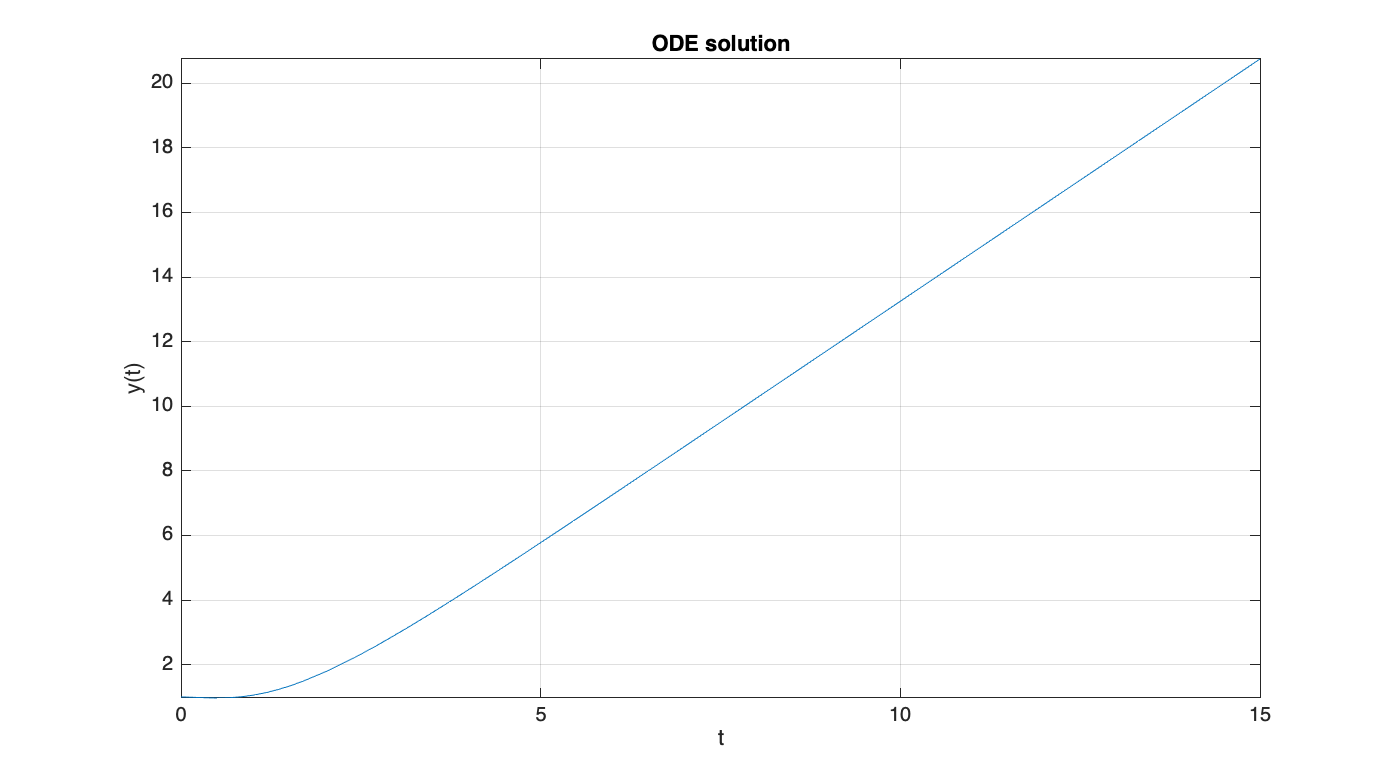

figure('Units','normalized','Position',[0.1,0.1,0.9,0.9])

fplot(ysol,[0 15])                      
title('ODE solution')
ylabel('y(t)')
xlabel('t')
grid on